# Simulación computacional de un péndulo

## Simulacion de un Péndulo

### Introducción

#### ¿Qué es un péndulo?

    El péndulo es un sistema físico formado por una masa suspendida de un punto fijo. Un péndulo se encuentra en reposo (equilibrio) cuando la fuerza del peso de la masa se contrarresta por la tensión de la cuerda o dispositivo del cual cuelga. No obstante, ese equilibrio se rompe al aplicar alguna fuerza externa: cuando se levanta un péndulo hacia un lado, la  fuerza de la gravedad quiere tirar de el hacia abajo y la tensión en la cuerda quiere tirar de el hacia la izquierda o derecha (siempre hacia el punto de pivote). Esas fuerzas combinadas trabajan juntas para tirar de él hacia el centro, es decir, a la posición de equilibrio. 

    Como se trata de un movimiento armónico simple, al llegar al centro, la velocidad del péndulo es mayor, por lo que continua más allá de la posición de equilibrio y hacia el lado contrario, el patrón continúa y cuanto más largo sea el cable utilizado en la creacion de un péndulo, más tardará el péndulo en completar un giro completo o periodo después de que se haya puesto en movimiento. Es importante mencionar que el movimiento de oscilación del péndulo también se ve afectado por otra fuerza aparte de las dos ya mencionadas, la resistencia del aire. Esta siempre se opone al movimiento de la masa colgante cuando se balancea hacia adelante y hacia atras, sin embargo, la fuerza de resistencia del aire es relativamente debil en comparación a las otras dos fuerzas. Aunque esto sea así, la fuerza del aire con el tiempo va generando una amortiguación, lo que se traduce en una gráfica senosoidal cada con cada vez menos amplitúd.

A continuación se presenta el desarrollo de la codificación para la simulación del péndulo **simple**. En esta simulación se trabajó con las ecuaciones existentes del movimiento de un péndulo simple para obtener los resultados exactos, y con el método de integración numérica de la regla del trapecio para comparar la posición generada con el método analítico y la generada por un método de integración numérica.

### Codificación de la simulación

#### Entrada de datos

    Lo primero que tenemos en nuestro programa son tres bucles while, los cuales se encargan de verificar que los datos que se están solicitando sean valores mayores a 0, de no ser así, habrá una iteración hasta que se ingresen números positivos. Se pide el largo del péndulo, la masa suspendida y la cantidad de oscilaciones.

l = 0;
while l <= 0
disp('Introduzca un valor positivo para el largo del pendulo')
l = input('¿Cuál será el largo del péndulo?');
end

m = 0;
while m <= 0
disp('Introduzca un valor positivo para la masa')
m = input('¿Cuánta será su masa?');
end

num = 0;
while num <= 0
disp('Introduzca un valor positivo para las oscilaciones') 
num = input('¿Cuántas oscilaciones desea?');
end

#### Constantes y variables calculadas 

    A continuación declaramos factores como la aceleración gravitacional y el ángulo del péndulo. También utilizamos todos los valores obtenidos para calcular la frecuencia, el periodo, la amplitud, la altura a la cual se eleva la masa y las oscilaciones. 

    Además, se crea un vector de tiempo que toma los valores de 0 hasta la varibale obtenida de oscilaciones, incrementando 0.1. En este punto, para ser mas específicos se establece la gravedad, que tiene un valor de 9.81. 

    La variable omega se obtiene a partir de la raíz cuadrada de la gravedad sobre el largo del péndulo: 


$$\omega =\sqrt{\frac{g}{l}}$$


    Después lo que viene siendo el periodo se calcula utilizando el valor de 2 por pi (π) sobre la omega anteriormente calculada:


$$\frac{2\pi }{\omega }=P$$


    Pasando a lo que es el ángulo theta (θ), este debe de tener un valor menor a los 20° debido a que se está programado una simulación de un péndulo simple.

    La amplitud, que es la distancia desde el péndulo en su punto mas alto hasta la vertical, se obtiene a partir de la de la longitud del péndulo (ya anteriormente calculada) por el seno del ángulo theta (también anteriormente establecido).  


$$A=\mathrm{lsin}\left(\theta \right)$$


    La altura utiliza el mismo principio que el anterior, solo que en este caso se le resta a la longitud el mismo valor de la longitud multiplicado por el coseno del ángulo theta.


$$h=l-\mathrm{lcos}\left(\theta \right)\;$$


    Para terminar con esta sección se obtiene lo que son las oscilaciones a realizar a partir de multiplicar lo que es el periodo por un valor introducido anteriormente por el usuario.

g = 9.81;
w = sqrt(g/l);
P = (2*pi)/w;
theta = 20;
A = l*sind(theta);
h = (l-l*cosd(theta));
osc = num * P;

%Vector de tiempo
t = 0:0.1:osc;

#### Definición de ecuaciones a utilizar

    A partir de funciones anónimas, creamos las ecuaciones de posición, velocidad y aceleración, las cuales tienen al tiempo como variable independiente. Después de la declaración de las funciones, utilzamos éstas y el vector de tiempo para generar vectores con todos los valores obtenidos de posición, velocidad y aceleración. La posición que obtenemos es la horizontal, la cual va de x a -x. Al ser ésta horizontal, su derivada, la velocidad, también es horizontal y no la angular. Las funciones matemáticas son las siguientes: 


$$s\left(t\right)=\mathrm{Acos}\left(\omega t+\phi \right)$$



$$v\left(t\right)=-A\omega^2 \mathrm{cos}\left(\omega t+\phi \right)$$



$$a\left(t\right)=-A\omega^2 \mathrm{cos}\left(\omega t+\phi \right)$$
 

Fs = @(t)  A.*cos(w.*t + 0);
Fv = @(t) -A.*w.*sin(w.*t + 0);
Fa = @(t) -A.*w.^2.*cos(w.*t +0);

s = Fs(t);
v = Fv(t);
a = Fa(t);

#### Integración con la regla del trapecio

    Utilizamos la regla del trapecio $T=\frac{h}{2}\left(f\left(x_0 \right)+f\left(x_n \right)+2\sum_{i=1}^{n-1} f\left(x_i \right)\right)$para obtener aproximaciones de la posición a partir la velocidad. Para este método de integración necesitamos el número de trapecios y el intervalo en el cual se quiere integrar. Lo anterior lo obtenemos a partir de la función length, la cual nos da el tamanño del vector de tiempo, el cual se vuelve el número de puntos que tendremos al aproximar. El intervalo lo determinamos desde 0 hasta el número de oscilaciones determinado por el usuario. Utilizamos un ciclo for porque para encontrar un punto 'x' se suma el área obtenida hasta el punto anterior a éste más el área obtenida en ese mismo punto 'x'.

Npoints = length(t);
a = 0;
b = osc;
x_p = t;
Vx_p = Fv(x_p);

Sa = zeros(size(t));
Sa(1) = s(1);
for i=2:Npoints-1
    ai = x_p(i);
    bi = x_p(i+1);
    
    fai = Vx_p(i);
    fbi = Vx_p(i+1);
    
    Ai = (fbi+fai) * (bi-ai)/2;
    
    Sa(i) = Sa(i-1) + Ai;
    
end
ai = x_p(i);
        bi = x_p(end);
    
        fai = Vx_p(end-1);
        fbi = Vx_p(end);
    
        Ai = (fbi+fai) * (bi-ai)/2;
        
Sa(end) = Sa(end-1)+Ai;

#### Ecuaciones de energía potencial y cinética

    Al igual que con las ecuaciones anteriores, definimos las funciones de energía potencial y energía cinética del péndulo y las utilizamos para obtener todos sus valores posibles empleando el vector de tiempo. En este caso se obtiene lo que es la energía total del sistema buscando la energía potencial máxima, pues la energía mecánica (que es toda la energía del sistema) nunca cambia y es igual a la suma de la potencial y la cinética en cada instante de tiempo, por lo que al encontrar la energía potencial máxima, también se encuentra que la energía cinética es igual a 0, lo que a su vez nos da la energía total del sistema con la energía potencial máxima.

EK = @(v) (1/2).*m.*v.^2;
eK = EK(v);
eU = m*g*h;
E = eU;

FU = @(t) E.*(cos(w.*t)).^2; 
FK = @(t)  E.*(sin(w.*t)).^2;

U = FU(t);
K = FK(t);

#### Figura para ejes de graficación

    Creamos una figura, la cual dividimos en cinco partes para mostrar las gráficas de posición, velocidad, energía y la simulación del movimiento del péndulo. Se utiliza la función de subplot para determinar en qué parte de la ventana Figura se encontrará cada gráfica.

figure("Name", "Simulacion péndulo simple", "NumberTitle", "off");
pendulum = subplot(3,2,[1,3,5]);
posicion = subplot(3,2,2);
velocidad = subplot(3,2,4);
energia = subplot(3,2,6);

#### Graficación

    Establecemos los intervalos de las gráficas, les damos nombre a los ejes y le asignamos colores y títulos para diferenciarlas. Después, empleando un ciclo for, accedemos a cada elemento (o resultado) de los vectores de velocidad, posición y energía, y los graficamos. También incluimos una pausa de 0.1 para mejorar la visibilidad de la animación confome al vector de tiempo, para el cual habíamos elegido un paso de 0.1, de esta manera, las animaciones se sincronizan y no se desfasan entre ellas. En este punto se utilizó lo que es la función de animatedline para poder animar la graficación de cada uno de nuestros puntos. Dentro del argumento que recive la misma función se le cambió el color a las gráficas para poder distinguirlas, mientras que también se les agregó una leyenda. 

title(pendulum,'Simulacion del pendulo');
xlim(pendulum, [-A-1, A+1]);
ylim(pendulum, [-l, 0]);
xlabel(pendulum, 'S(t)')
ylabel(pendulum, 'h')

title(posicion, 'S(t)');
xlim(posicion, [0, osc]);
ylim(posicion, [-A, A]);
xlabel(posicion, 't')
ylabel(posicion, 'S')

title(velocidad, 'V(t)');
xlim(velocidad, [0, osc]);
ylim(velocidad, [-A*w, A*w]);
xlabel(velocidad, 't')
ylabel(velocidad, 'V')

title(energia, 'E(t)');
xlim(energia, [0, osc]);
ylim(energia, [0, E+1]);
xlabel(energia, 't')
ylabel(energia, 'E')

posi = animatedline(posicion, 'Color', 'r');
veloci = animatedline(velocidad, 'Color', 'm');
energia_cinetica = animatedline(energia, 'Color', 'g');
energia_potencial = animatedline(energia,'Color', 'r');
pend = animatedline(pendulum,'Marker','o','MarkerFaceColor', 'b', 'MarkerSize', 10);
legend('Energia cinetica','Energia potencial');

for k = 1:length(t)
       addpoints(posi, t(k), s(k));
       addpoints(veloci, t(k), v(k));
       addpoints(energia_cinetica, t(k),K(k));
       addpoints(energia_potencial, t(k), U(k));
       addpoints(pend, s(k), -1*sqrt((l.^2)-(s(k).^2)));
       addpoints(pend, [0;s(k)],[0;-1*sqrt((l.^2)-(s(k).^2))])
       pause(.1);
       cla(pendulum);
       pendulum = subplot(3,2,[1,3,5]);
       pend = animatedline(pendulum,'Marker','o','MarkerFaceColor', 'b', 'MarkerSize', 10); 
       
end

close all


#### Posición aproximada contra posición exacta

    Obtenemos los resultados de los valores de posición obtenidos al inicio del programa con las ecuaciones del péndulo y las aproximaciones generadas al integrar la velocidad con la regla del trapecio. Comparamos estos resultados graficando cada elemento de sus respectivos vectores de posición en una misma gráfica. Aquí termina el programa.

hold on
plot(t, s, 'Color', 'r')
xlabel('Tiempo (t)')
ylabel('Posición (s)')
plot(t, Sa, 'Color', 'b')
legend('Posición exacta','Posición Aproximada')
hold off

#### Output del programa

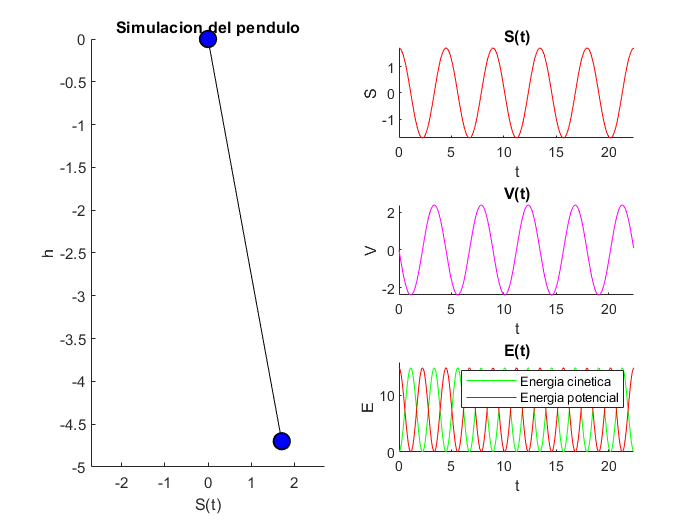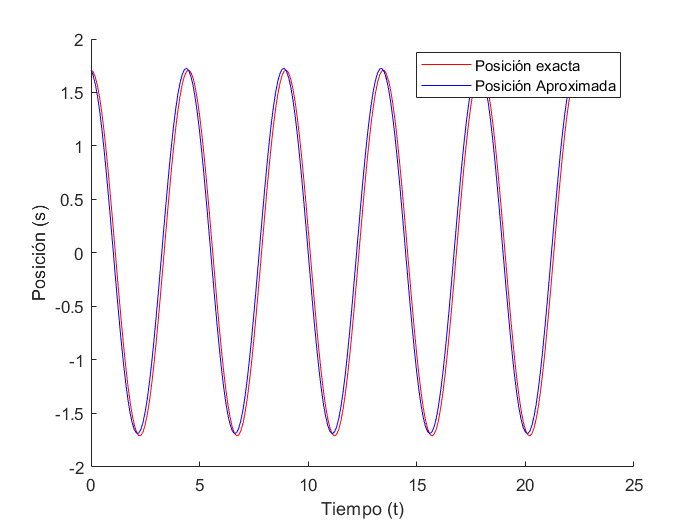

#### Referencias

movarm. (2020). EL MOVIMIENTO ARMÓNICO SIMPLE. Recuperado noviembre 7, 2020, de Unirioja.es         Sitio web: [https://www.unirioja.es/dptos/dq/fa/pract_it/movarm/movarm.html](https://www.unirioja.es/dptos/dq/fa/pract_it/movarm/movarm.html)

Trigonometría y fuerzas: el péndulo (artículo) | Khan Academy. (2018). Recuperado noviembre 7, 2020, de Khan Academy Sitio web: [https://es.khanacademy.org/computing/computer-programming/programming-natural-simulations/programming-oscillations/a/trig-and-forces-the-pendulum](https://es.khanacademy.org/computing/computer-programming/programming-natural-simulations/programming-oscillations/a/trig-and-forces-the-pendulum)

(2020). El péndulo. Recuperado noviembre 10, 2020, de Sc.ehu.es Sitio web: [http://www.sc.ehu.es/sbweb/fisica/oscilaciones/pendulo2/pendulo2.htm](http://www.sc.ehu.es/sbweb/fisica/oscilaciones/pendulo2/pendulo2.htm)

The physics classroom. (s.f.). Pendulum motion. Recuperado de 

[https://www.physicsclassroom.com/class/waves/Lesson-0/Pendulum-Motion](https://www.physicsclassroom.com/class/waves/Lesson-0/Pendulum-Motion)

Movimiento circular uniformemente variado. (s.f.). Recuperado de

[https://es.khanacademy.org/science/fisica-pe-pre-u/x4594717deeb98bd3:movimiento-rectilineo-uniformemente-variado-mruv/x4594717deeb98bd3:movimiento-circular/a/movimiento-circular-uniformemente-variado-repaso](https://es.khanacademy.org/science/fisica-pe-pre-u/x4594717deeb98bd3:movimiento-rectilineo-uniformemente-variado-mruv/x4594717deeb98bd3:movimiento-circular/a/movimiento-circular-uniformemente-variado-repaso)

Serway, A., Jewett, W., (2019). *Physics for Scientists and Engineers (10th Edition), *Cengage Learning.

Colaboradores de los proyectos Wikimedia. (2002, enero 13). Péndulo. Recuperado noviembre 7, 2020, de Wikipedia.org Sitio web: [https://es.wikipedia.org/wiki/P%C3%A9ndulo](https://es.wikipedia.org/wiki/P%C3%A9ndulo)

Movimiento Armónico Simple en Péndulos. (2020). Recuperado noviembre 11, 2020, de Fisicalab.com Sitio web: [https://www.fisicalab.com/apartado/mas-y-pendulos](https://www.fisicalab.com/apartado/mas-y-pendulos)

Péndulos y tipos. (2014, septiebre 23).  Recuperado noviembre 11, 2020, de Wordpress.com Sitio web: [https://gsusj.wordpress.com/2014/09/23/pendulos-y-guia-para-su-uso/](https://gsusj.wordpress.com/2014/09/23/pendulos-y-guia-para-su-uso/)

Péndulo - EcuRed. (2020). Recuperado noviembre 10, 2020, de Wordpress.com Sitio web:  Ecured.cu website: [https://www.ecured.cu/P%C3%A9ndulo#Tipos_de_p.C3.A9ndulos](https://www.ecured.cu/P%C3%A9ndulo#Tipos_de_p.C3.A9ndulos)

Physics Tutorial: Pendulum Motion. (2020). Recuperado noviembre 10, 2020, de Physicsclassroom.com Sitio web: [https://www.physicsclassroom.com/class/waves/Lesson-0/Pendulum-Motion](https://www.physicsclassroom.com/class/waves/Lesson-0/Pendulum-Motion)

Pendulum. (2020). Recuperado noviembre 11, 2020, de Gsu.edu Sitio web: [http://hyperphysics.phy-astr.gsu.edu/hbase/pend.html](http://hyperphysics.phy-astr.gsu.edu/hbase/pend.html)

Taylor, S. (abril 24, 2017). History of the Pendulum. Recuperado noviembre 10, de SCIENCING Sitio web: [https://sciencing.com/history-pendulum-4965313.html](https://sciencing.com/history-pendulum-4965313.html)

Foucault Pendulum. (2020). Recuperado noviembre 12, de Smithsonian Institution Sitio web: [https://www.si.edu/spotlight/foucault-pendulum](https://www.si.edu/spotlight/foucault-pendulum)